# Lab 1: Numerical Integration

Define the parameters of the model:

m = 5; % kg
k1 = 2; % N/m
k2 = 3; % N/m
b = 15; % Ns/m
F = 1; % N

Define a time vector for your simulation. Define your time vector for 20 seconds (starting at t0 = 0 sec) in increments of 0.01 seconds.

t0 = 0;   % start time 
dt  = 0.01; % step size
tf = 20;   % end time

% Define time vector 
t = [t0:dt:tf];

Using the ‘length’ command determine the number of values in the time vector and store it in a variable N.

% Length of time array so we know the number of integration steps to make
N = length(t)

N = 2001

Initialize variables for (x=) and (x_dot= or xd=) using the ‘zeros’ command. This will create an array of zeros that will populate the array. Make each of the variables have 1 row and N columns of zeros. Consider what the initial conditions x(0) and x_dot(0) should be for this problem assuming that the mass is initially at rest with the system in equilibrium.

% Create placeholder arrays of zeros for the solution and the first
% derivative
x = zeros(1,N);
x_dot = zeros(1,N);

% Set initial conditions
x(1) = 0;
x_dot(1) = 0;

Create a ‘for’ loop to run your simulation. Your loop should iterate from i = 2 to N or from i = 1 to N-1, depending on how you are implementing your Euler integration. 

In your loop you should do the following steps:

a. Evaluate your equation of motion to determine x_ddot(t) at the current time step.

b. Use Euler integration to predict x_dot(t) at the next time step.

c. Use Euler integration to predict x(t) at the next time step.

for i = 1:N-1
    x_ddot = F/m - (b/m)*x_dot(i) - ((k1+k2)/m)*x(i);
    x_dot(i+1) = x_dot(i) + x_ddot*dt;
    x(i+1) = x(i) + x_dot(i)*dt;
end

7. Run your MATALB script and debug any errors that arise. If it works correctly, you should have an x array and an xd array the same size as your time vector. These vectors should have the data from the dynamic simulation contained within them.

t

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


x

x =          0         0    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0018    0.0021    0.0023    0.0026    0.0029    0.0032    0.0035    0.0038    0.0041    0.0045    0.0048    0.0052    0.0055    0.0059    0.0063    0.0066    0.0070    0.0074    0.0079    0.0083    0.0087    0.0091    0.0096    0.0100    0.0104    0.0109    0.0114    0.0118    0.0123    0.0128    0.0132    0.0137    0.0142    0.0147    0.0152


x_dot

x_dot =          0    0.0020    0.0039    0.0058    0.0076    0.0094    0.0111    0.0128    0.0144    0.0160    0.0175    0.0190    0.0204    0.0217    0.0231    0.0244    0.0256    0.0268    0.0280    0.0291    0.0302    0.0313    0.0323    0.0333    0.0343    0.0352    0.0361    0.0370    0.0378    0.0386    0.0394    0.0401    0.0409    0.0416    0.0422    0.0429    0.0435    0.0441    0.0447    0.0453    0.0458    0.0463    0.0468    0.0473    0.0477    0.0482    0.0486    0.0490    0.0494    0.0498


8. You can now plot these data. Create a Figure with two subplots:

a. Plot position vs time on the top plot.

b. Plot velocity vs time on the bottom plot.

c. Label your x and y axes for each of the subplots.

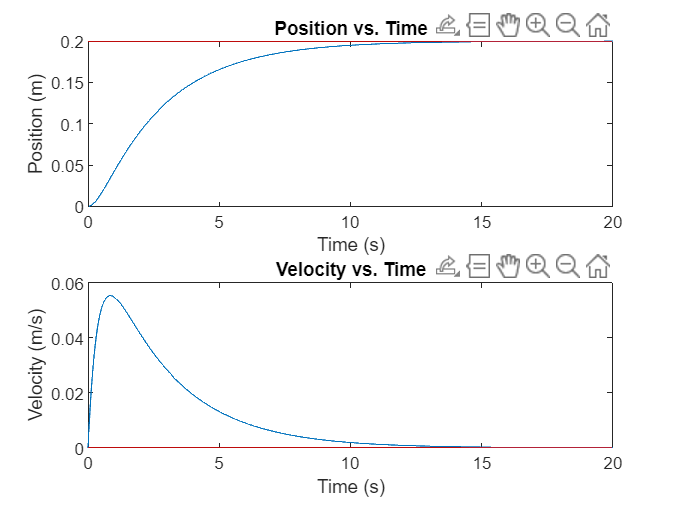

subplot(2,1,1)
plot(t, x)
yline(0.2, 'r')
title("Position vs. Time")
xlabel("Time (s)")
ylabel("Position (m)")

subplot(2,1,2)
plot(t, x_dot)
yline(0, 'r')
title("Velocity vs. Time")
xlabel("Time (s)")
ylabel("Velocity (m/s)")

9. Show your results to your instructor prior to beginning the Analysis section.